# **Final Project - Adaptive Cruise Control Model**

**Gurpo 1**: Adaptive Cruise Control 

**Authors:** Gabriel Lopes Lomeu Reis Oliveira;  Leonardo de Melo Abreu Lucas de Carvalho Sobral; Matheus Henrique de Souza Passos; Vitor Fassanaro Cortez de Carvalho

This code demonstrates how adaptive cruise control was modeled for the final project of the technology residency.

The goal is to have an ego car travel at a speed chosen by the user or automatically adjust its speed to match the vehicle ahead while maintaining a safe distance between vehicles. This is achieved by controlling longitudinal acceleration.

## **Adaptive Cruise Control System**

The Adaptive Cruise Control (ACC) system is a technology developed to assist vehicles in maintaining a safe distance from other cars and staying within established speed limits. A car equipped with the ACC system (ego car) uses sensors to assess the relative distance ($D_{rel}$) and relative velocity ($V_{rel}$)  in relation to the vehicle ahead. The purpose of the ACC system is to maintain a desired cruise speed ($V_{set}$) or preserve a relative safe distance ($D_{safe}$) from the car in front. The change in the control objective is determined based on the following conditions.

- If $D_{rel} > D_{safe}$, the ACC system follows the desired reference cruise velocity commanded by the driver;

- If $D_{rel} < D_{safe}$, the ACC system controls the relative position of the ego car with respect to the lead car.

**Configuration of parameters for the ACC**

%v_set     = 80;   % Driver-set velocity.....................(Km/h)
D_default = 10;   % Default spacing.........................(m)
Time_Gap  = 3;    % Time gap................................(s)
amin_ego  = -5;   % Minimum acceleration for driver comfort (m/s^2)
amax_ego  = 1.47; % Maximum acceleration for driver comfort (m/s^2)
Ts        = 0.1;  % Sample time.............................(s)   
Tf        = 500;  % Duration................................(s)

%Gain values
Kverr_gain = 0.5; % ACC velocity error gain.................(N/A)
Kxerr_gain = 0.2; % ACC spacing error gain..................(N/A)
Kvx_gain   = 0.4; % ACC relative velocity gain..............(N/A)

%External Variables
m                  = 0.5; % 
b                  = 1;   % 
%ACC_input          = 1; % When "1" ACC is on, when "0" ACC is off
Fault_signal       = false; % When "1" system failure, when "0" system is operatinal
Gas_Pedal_Sensor   = false; % When "0" pedal not pressed, when "1" pedal pressed
Brake_Pedal_Sensor = false; % When "0" pedal not pressed, when "1" pedal pressed


**Inicial position for lead car and ego car**

x0_lead = 50;  % Initial lead car position (m)
x0_ego  = 10;  % Initial ego car position..(m)

**Inicial velocity for lead car and ego car**

v0_lead = 90; % Initial lead car position (Km/h)
v0_ego  = 70; % Initial ego car position..(Km/h)

**Simulink model**

model= 'ACC_simu';
open_system(model)
% Run the simulation
sim(model);

time_gap_out =
     3



**Results **

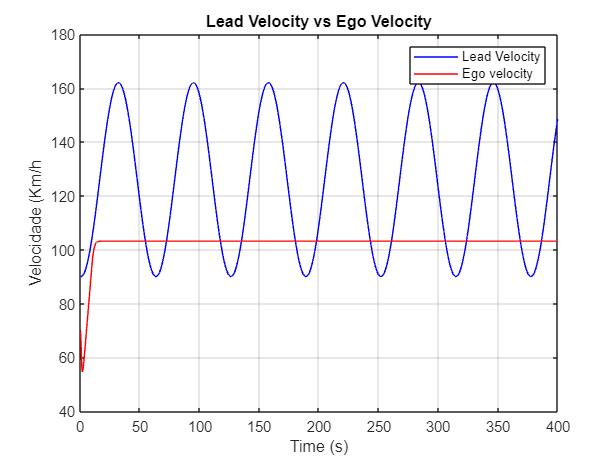

%Create plot of Lead_Velocity_Time and Lead_Velocity_Data
figure;
plot(out.Lead_Velocity.time,out.Lead_Velocity.Data,'b',out.Ego_Velocity.time,out.Ego_Velocity.Data,'r');
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Velocidade (Km/h');
title('Lead Velocity vs Ego Velocity');
legend('Lead Velocity', 'Ego velocity');
grid on;